files = {'hood_m.wav', 'hood_f.wav'};

function [fs, duration, numSamples] = playAudio(fileName)
    fileName = strcat('speech/',fileName);
    [audio, fs] = audioread(fileName);
    duration = length(audio) / fs;
    numSamples = length(audio);
    fprintf('Playing %s at %d Hz with duration %.2f seconds and %d samples\n',fileName, fs, duration, numSamples);
    figure;
    spectrogram(audio, hamming(256), 128, 1024, fs, 'yaxis');
    title(['Spectrogram of ', fileName]);
    sound(audio, fs);
    pause(duration + 1) 
end

Playing speech/hood_m.wav at 24000 Hz with duration 0.18 seconds and 4429 samples


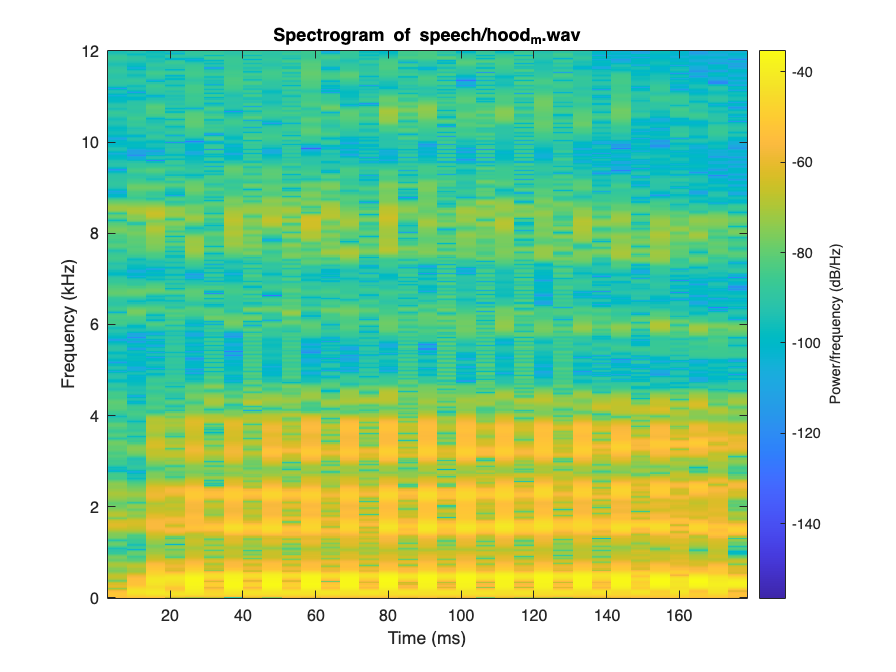

Playing speech/hood_f.wav at 24000 Hz with duration 0.24 seconds and 5791 samples


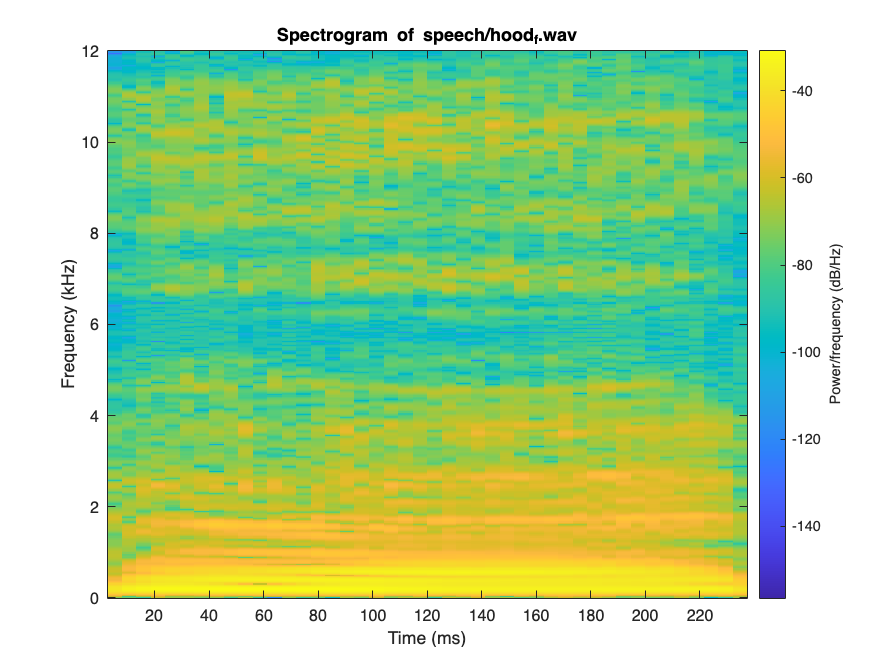

segmentDuration = 0.1;

for i = 1:length(files)
    [fs, duration, numSamples] = playAudio(files{i});  % Use the index i to access files
    numSegmentSamples = segmentDuration * fs;
end